% This script prepares experimental electron ptycho. data for PtychoShelves

## Step 1: download the sample data from the PARADIM website:

[https://data.paradim.org/doi/ssmm-2j11/](https://data.paradim.org/doi/ssmm-2j11/) Note: it's a good practice to store data (and reconstructions) in a different folder from fold_slice 

## Step 2: load data

data_dir = '/Users/klmendozatrujillo/Library/CloudStorage/Box-Box/KLMT_Work/Electron_Ptychography/MATLAB/fold_slice_sample_data/PrScO3/'; %change this
load(strcat(data_dir,'example_data_PrScO3.mat'))

## Step 3: go back to .../fold_slice/ptycho and pre-process data

addpath(strcat(pwd,'/utils_electron/'))
Np_p = [256,256]; % size of diffraction patterns used during reconstruction. can also pad to 256
% pad cbed
[ndpy,ndpx,npy,npx]=size(dp);
if ndpy < Np_p(1) % pad zeros
    dp=padarray(dp,[(Np_p(1)-ndpy)/2,(Np_p(2)-ndpx)/2,0,0],0,'both');
else
    dp=crop_pad(dp,Np_p);
end

dp = dp / ADU; % convert to electron count
dp=reshape(dp,Np_p(1),Np_p(2),[]);
Itot=mean(squeeze(sum(sum(dp,1),2))); %need this for normalizting initial probe

% calculate pxiel size (1/A) in diffraction plane
[~,lambda]=electronwavelength(voltage);

rbf=26; % radius of center disk in pixels
dk=alpha/1e3/rbf/lambda; %%% PtychoShelves script needs this %%%

## Step 4: save CBED in a .hdf5 file (needed by Ptychoshelves)

scan_number = 1; %Ptychoshelves needs
save_dir = strcat(data_dir,num2str(scan_number),'/');
mkdir(save_dir)
roi_label = '0_Ndp256';
saveName = strcat('data_roi',roi_label,'_dp.hdf5');
h5create(strcat(save_dir,saveName), '/dp', size(dp),'ChunkSize',[size(dp,1), size(dp,2), 1],'Deflate',4)
h5write(strcat(save_dir,saveName), '/dp', dp)

## Step 5: prepare initial probe

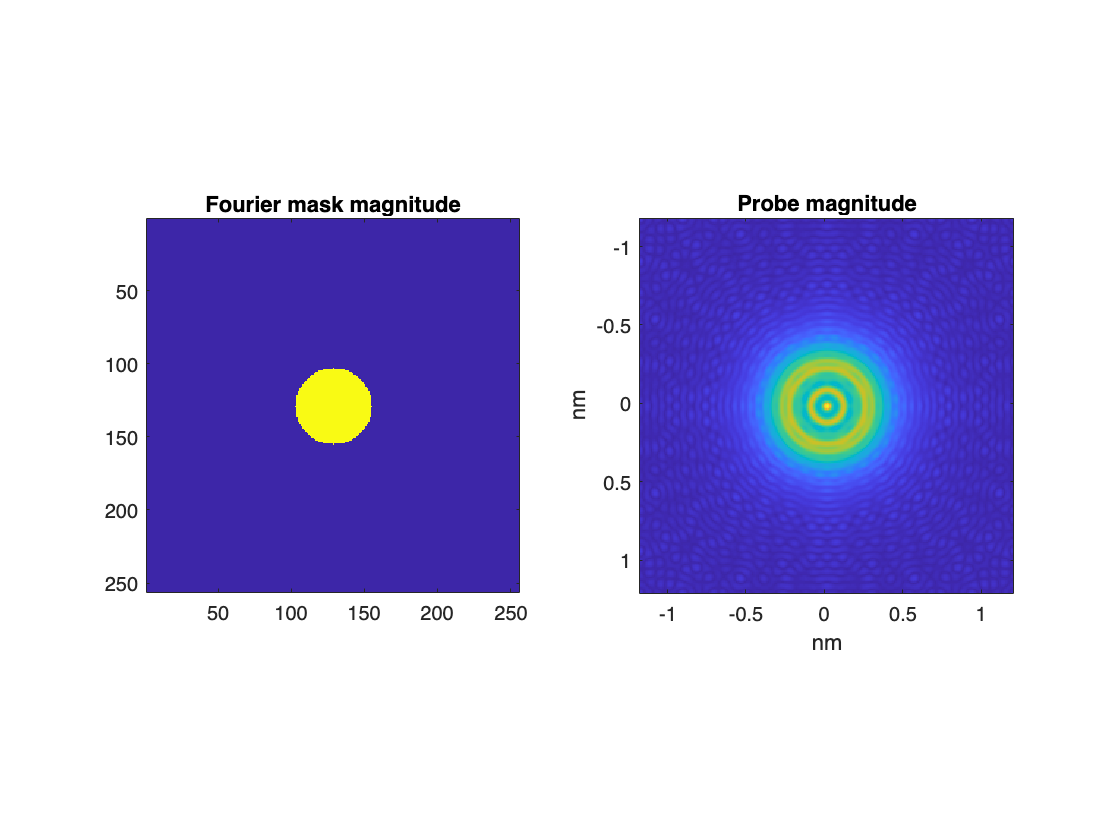

dx=1/Np_p(1)/dk; %% pixel size in real space (angstrom)

par_probe = {};
par_probe.df = defocus;
par_probe.voltage = voltage;
par_probe.alpha_max = alpha;
par_probe.plotting = true;
probe = make_tem_probe(dx, Np_p(1), par_probe);


probe=probe/sqrt(sum(sum(abs(probe.^2))))*sqrt(Itot)/sqrt(Np_p(1)*Np_p(2));
probe=single(probe);
% add parameters for PtychoShelves
p = {};
p.binning = false;
p.detector.binning = false;

## Step 6: save (or load) initial probe

%save(strcat(save_dir,'/init_probe.mat'),'probe','p')
load(strcat(data_dir,'/1/init_probe.mat'))